% Load the training data 
data = load("aug4signs_trainingdata_new.mat");
signsDataset = data.trainingData;

signsDataset(1:4,:)

ans = 4×2 table
                                           imageFilename                                               TrafficSign     
    ___________________________________________________________________________________________    ____________________

    {'D:\college\FYP\Dataset\ObjectDetection\TrafficSigns\Crossing\resize_crossing (1).jpg'   }    {[ 271 757 248 233]}
    {'D:\college\FYP\Dataset\ObjectDetection\TrafficSigns\Crossing\resize_crossing (1)_a2.jpg'}    {[ 563 936 246 231]}
    {'D:\college\FYP\Dataset\ObjectDetection\TrafficSigns\Crossing\resize_crossing (1)_a4.jpg'}    {[ 564 754 248 232]}
    {'D:\college\FYP\Dataset\ObjectDetection\TrafficSigns\Crossing\resize_crossing (2).jpg'   }    {[1296 369 585 546]}


Split the dataset into training, validation, and test sets. Select 60% of the data for training, 10% for validation, and the rest for testing the trained detector.

rng("default");
shuffledIndices = randperm(height(signsDataset));
idx = floor(0.6 * length(shuffledIndices) );

trainingIdx = 1:idx;
trainingDataTbl = signsDataset(shuffledIndices(trainingIdx),:);

validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = signsDataset(shuffledIndices(validationIdx),:);

testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = signsDataset(shuffledIndices(testIdx),:);

Use `imageDatastore` and `boxLabelDatastore` to create datastores for loading the image and label data during training and evaluation.

imdsTrain = imageDatastore(trainingDataTbl{:,"imageFilename"});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,"TrafficSign"));

imdsValidation = imageDatastore(validationDataTbl{:,"imageFilename"});
bldsValidation = boxLabelDatastore(validationDataTbl(:,"TrafficSign"));

imdsTest = imageDatastore(testDataTbl{:,"imageFilename"});
bldsTest = boxLabelDatastore(testDataTbl(:,"TrafficSign"));

Combine image and box label datastores.

trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);

Display one of the training images and box labels.

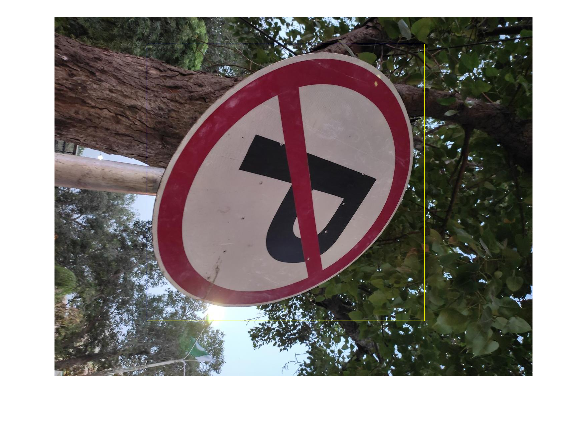

data = read(trainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,"Rectangle",bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

reset(trainingData);

**Create a YOLO v4 Object Detector Network**

inputSize = [608 608 3];
className = "TrafficSign";

rng("default")
trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));
numAnchors = 9;
[anchors,meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors);

area = anchors(:, 1).*anchors(:,2);
[~,idx] = sort(area,"descend");

anchors = anchors(idx,:);
anchorBoxes = {anchors(1:3,:)
    anchors(4:6,:)
    anchors(7:9,:)
    };

detector = yolov4ObjectDetector("csp-darknet53-coco",className,anchorBoxes,InputSize=inputSize);

**Perform Data Augmentation**

Perform data augmentation to improve training accuracy. Use the `transform` function to apply custom data augmentations to the training data. The `augmentData` helper function applies the following augmentations to the input data:

- Color jitter augmentation in HSV space

- Random horizontal flip

- Random scaling by 10 percent

Note that data augmentation is not applied to the test and validation data. Ideally, test and validation data should be representative of the original data and is left unmodified for unbiased evaluation.

augmentedTrainingData = transform(trainingData,@augmentData);

Read and display samples of augmented training data.

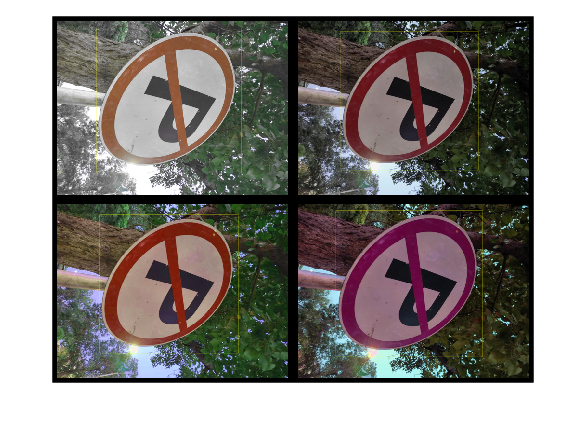

augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1},"rectangle",data{2});
    reset(augmentedTrainingData);
end
figure
montage(augmentedData,BorderSize=10)

**Specify Training Options**

options = trainingOptions("adam",...
    GradientDecayFactor=0.9,...
    SquaredGradientDecayFactor=0.999,...
    InitialLearnRate=0.001,...
    LearnRateSchedule="none",...
    MiniBatchSize=4,...
    L2Regularization=0.0005,...
    MaxEpochs=30,...
    BatchNormalizationStatistics="moving",...
    ResetInputNormalization=false,...
    Shuffle="every-epoch",...
    VerboseFrequency=20,...
    ValidationFrequency=1,...
    CheckpointPath=tempdir,...
    ValidationData=validationData);

**Train YOLO v4 Object Detector**

[detector,info] = trainYOLOv4ObjectDetector(augmentedTrainingData,detector,options);

*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* TrafficSign

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _____    _________    ___________    _________    ____________    ______________


**Supporting Functions**

function data = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.

data = cell(size(A));
for ii = 1:size(A,1)
    I = A{ii,1};
    bboxes = A{ii,2};
    labels = A{ii,3};
    sz = size(I);

    if numel(sz) == 3 && sz(3) == 3
        I = jitterColorHSV(I,...
            contrast=0.0,...
            Hue=0.1,...
            Saturation=0.2,...
            Brightness=0.2);
    end
    
    % Randomly flip image.
    tform = randomAffine2d(XReflection=true,Scale=[1 1.1]);
    rout = affineOutputView(sz,tform,BoundsStyle="centerOutput");
    I = imwarp(I,tform,OutputView=rout);
    
    % Apply same transform to boxes.
    [bboxes,indices] = bboxwarp(bboxes,tform,rout,OverlapThreshold=0.25);
    labels = labels(indices);
    
    % Return original data only when all boxes are removed by warping.
    if isempty(indices)
        data(ii,:) = A(ii,:);
    else
        data(ii,:) = {I,bboxes,labels};
    end
end
end

function data = preprocessData(data,targetSize)
% Resize the images and scale the pixels to between 0 and 1. Also scale the
% corresponding bounding boxes.

for ii = 1:size(data,1)
    I = data{ii,1};
    imgSize = size(I);
    
    bboxes = data{ii,2};

    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);
    
    data(ii,1:2) = {I,bboxes};
end
end